## Image segmentation using region growing

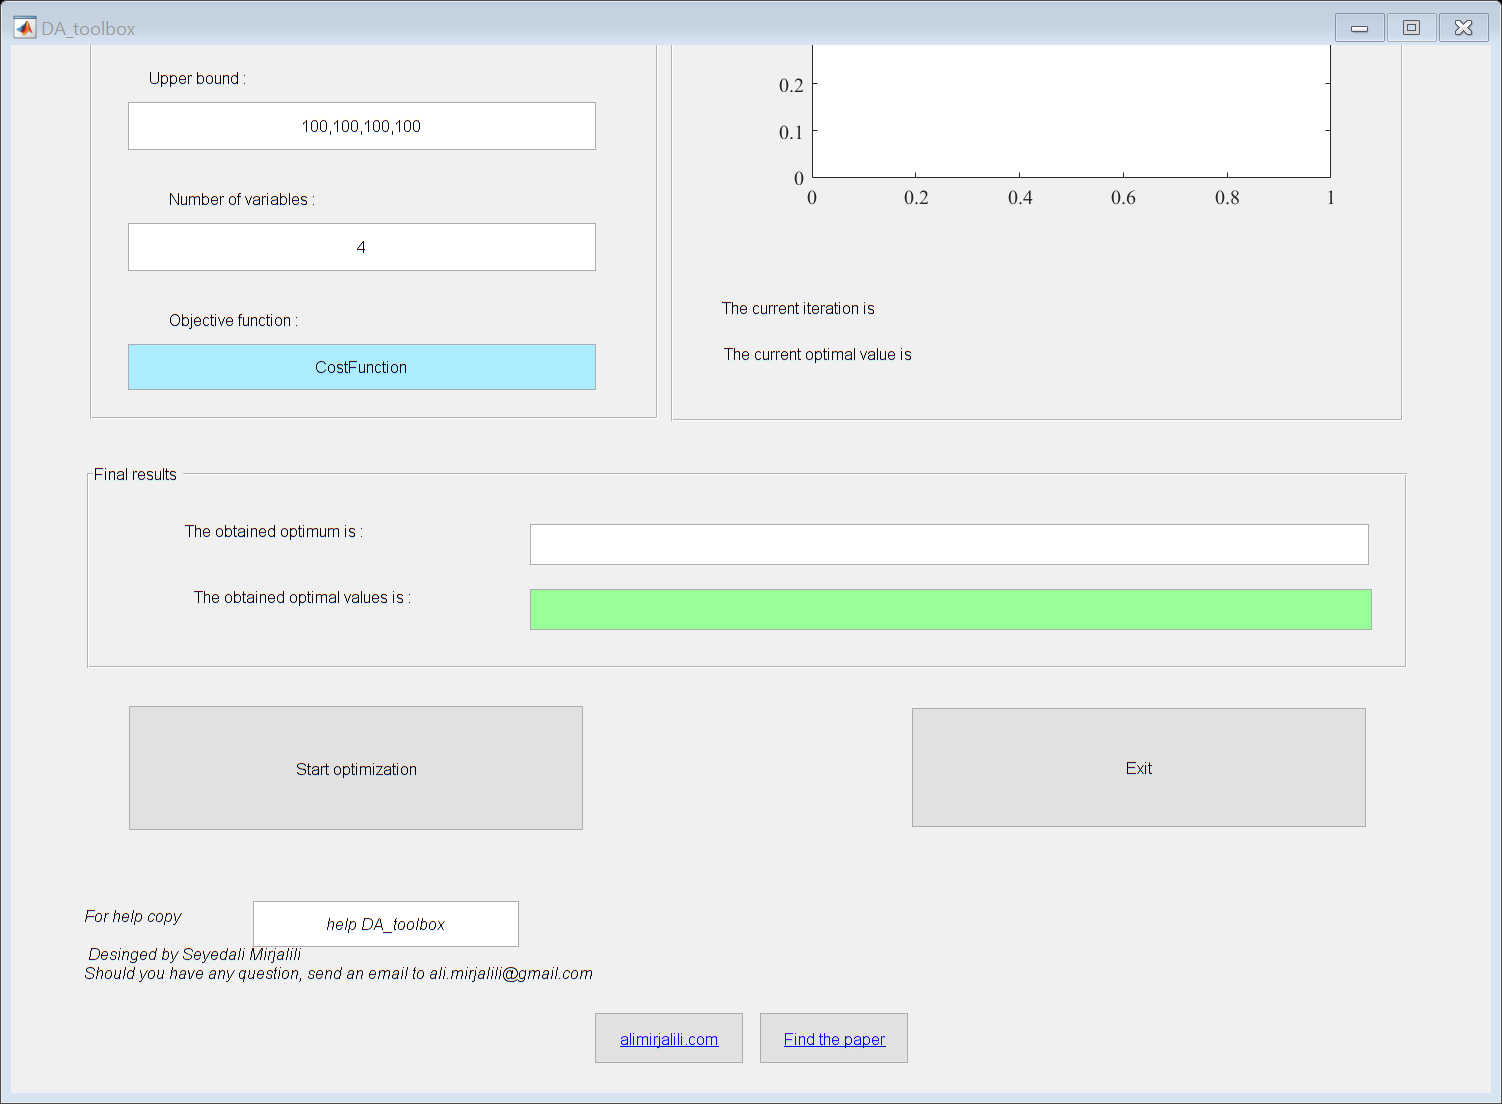

breastImds="mdb001.tiff";

%put images file location here
%breastImds = imageDatastore(...
%    "C:\Users\Daniel Kee\Documents\Monash\FYP\FIT3162\fit3162\Code\MIAS(no muscle)");
%img="MIAS(no muscle)/mdb020.jpg";

sd=DA_toolbox(breastImds);

region_growing(breastImds,180);

Check for missing argument or incorrect argument data type in call to function 'read'.

Error in RegionGrowing>region_growing (line 12)
I = read(breastImds);

region_growing(breastImds,sd);

function region_growing(breastImds,seed)
I = read(breastImds);
I = rgb2gray(I);

I = double(I);
figure, subplot(2,2,1),imshow(uint8(I)),title('Original Image');
Seeds = [seed];
SI = I == Seeds;
subplot(2,2,2), imshow(SI, []),title('Pixel value = 200 (Seeds)');
T = 30;
TI = false(size(I));

for i = 1:length(Seeds)
    seed_val = Seeds(i);
    S = abs(I-seed_val) <= T;
    TI = TI | S;
end

subplot(2,2,3), imshow(TI, []),title('Pixels connected with seeds');
IM = imreconstruct(SI,TI);
subplot(2,2,4), imshow(IM, []),title('Segmented image');
end